# Discretización y control respirador

## 1. Discretización del sistema

El sistema pulmones-caja toracica se ha modelado como un sistema viscoeslastico que sigue la siguiente ecuación diferencial:


$$R_m\cdot E_m \cdot Q+E_m \cdot E \cdot V+R_m \cdot E \cdot  Q=E_m \cdot P_a+R_m\dot{P}_a$$


donde $Q
$ es el flujo de aire que tiene como entrada el sistema, $V$ y $P_a
$ son el volumen y presión de aire que entra a los pulmones, respectivamente. 

Por otra parte, $R_m
$ es el coeficiente de elásticidad de los pulmones, $E_m
$ la eslasticidad de los pulmones y $E$ la elasticidad de la caja torácica.

Sabemos que $Q$ se corresponde con $Q=\frac{dV}{dt}$, por lo que podriamos escribir la ecuación anterior como:


$$R_m\cdot E_m \cdot\dot{V}+E_m \cdot E \cdot V+R_m \cdot E \cdot  \dot{V}=E_m \cdot P_a+R_m\dot{P}_a$$


Para obtener el modelo se calcularán las matrices A, B, C, D de la descripción de interna, tomando como vector de estados $x=[P_a\ V]$

En primer lugar vamos a definir las constantes:

Rm=2000;     % Viscosidad de los pulmones.
Em=4000;     % Elasticidad de los pulmones.
E= 1000;     % Elasticidad caja torácica.

Ahora vamos a definir las matrices:

A=[-Em/Rm Em*E/Rm; 0 0]; B=[Em+E;1]; C=[1 0]; D=0;

El sistema en descripción interna sigue la siguiente estructura:


$$\dot{x}=Ax+Bu
$$



$$y=Cx+Du$$


Si empezamos en un tiempo $t_0$ tiene como solución:


$$x\left(t\right)=\phi\left(t-t_0\right)x\left({t_0}\right)+\int_{t_0}^{t}\phi\left(t-\tau\right)Bu\left(\tau\right)d\tau$$


Si tomamos $t=\left(K+1\right)T$ y $t_0=KT$, se puede obtener la función discreta del sistema:


$$x\left(KT+T\right)=\phi\left(T\right)x\left(KT\left)+\int_{KT}^{KT+T}\phi\left(KT+T-\tau\right)Bu\left(\tau\right)d\tau$$


Como $u\left(t)$permanece constante en un tiempo de muestreo:


$$x\left(KT+T\right)=\phi\left(T\right)x\left(KT\left)+\left(\int_{KT}^{KT+T}\phi\left(KT+T-\tau\right)Bd\tau\right)u\left(KT\right)
$$


Si llamamos a $G$ a la matriz $A$  y $H$ a la matriz $B$ en discreto, podemos llegar a al conculsión que:


$$x\left(KT+T\right)=\underbrace{\phi\left(T\right)}_{G}\ x\left(KT\left)+\underbrace{\left(\int_{KT}^{KT+T}\phi\left(KT+T-\tau\right)Bd\tau\right)}_{H}u\left(KT\right)
$$


Donde $\phi=e^{AT}$

Vamos a hacer uso del lenguaje simbolico para el calculo de la integral y posteriormente probaremos con diferentes tiempos de muestreo para verificar su correcta discretización.

syms t tau real;
H=int(expm(A*(t-tau))*B,tau,0,t)

$$H = \left(\begin{array}{c} 1000\,t-2000\,{\mathrm{e}}^{-2\,t}+2000\\ t \end{array}\right)$$

G=expm(A*t)

$$G = \left(\begin{array}{cc} {\mathrm{e}}^{-2\,t} & 1000-1000\,{\mathrm{e}}^{-2\,t}\\ 0 & 1 \end{array}\right)$$

Una vez hecho este calculo simbolico vamos podemos calcular las matrices discretas.

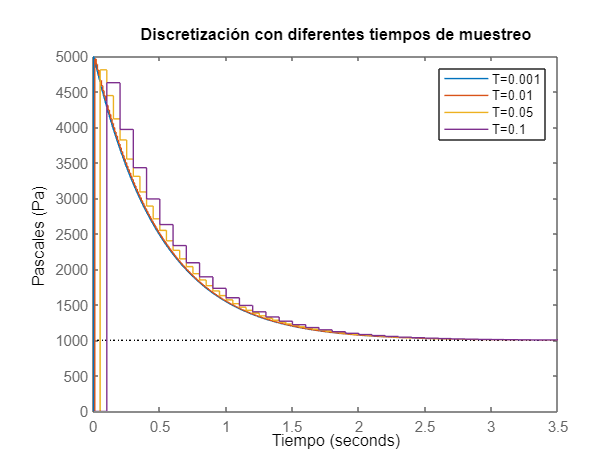

T=[0.001 0.01 0.05 0.1]; %Diferentes tiempos de muestreo
for k=1:length(T)
    G=[exp(-2*T(k)) 1000-1000*exp(-2*T(k));0 1];
    H=[1000*T(k)-2000*exp(-2*T(k))+2000;T(k)];
    Cd=[1 0];
    Dd=0;
    r(1:2,k)=eig(G);
    z=tf('z',T(k));
    I=eye(size(G));
    Gd=Cd*inv(z*I-G)*H+Dd;
    impulse(Gd)
    hold on
end
legend(strcat('T= ',num2str(T(1))),strcat('T= ',num2str(T(2))),strcat('T= ',num2str(T(3))),strcat('T= ',num2str(T(4))));
title('Discretización con diferentes tiempos de muestreo')
ylabel('Pascales (Pa)')
xlabel('Tiempo');
hold off

Para que el sistema sea estable se tiene que cumplir que los autovalores del sistema discretizado sean $<1$, ya que como sabemos, en tiempo discreto los polos se deben de encontrar dentro del circulo unidad. Ahora, vamos a analizar los autovalores de la matriz G para los diferentes tiempos de muestreo usados, para verificar, como podemos ver en la entrada impulso, que el sistema se mantiene estable para diferentes tiempos de muestreo.

r

r =     0.9980    0.9802    0.9048    0.8187
    1.0000    1.0000    1.0000    1.0000


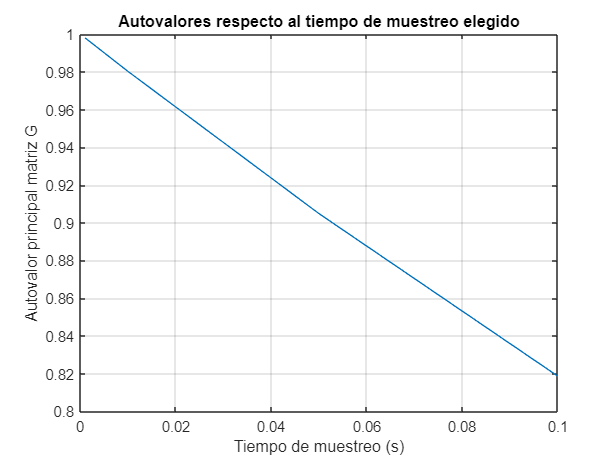

plot(T,r(1,:))
title('Autovalores respecto al tiempo de muestreo elegido');
xlabel('Tiempo de muestreo (s)');
ylabel('Autovalor principal matriz G')
grid;

Una vez hecho esto, y observando la gráfica de la respuesta del sistema ante entrada impulso, vemos que ofrece resultados similares hasta un tiempo de muestreo de 0.1 segundos, por lo que tomaremos 0.01 segundo para trabajar con ella. 

T=0.02;
z=tf('z',T);
G=[exp(-2*T) 1000-1000*exp(-2*T);0 1]

G =     0.9608   39.2106
         0    1.0000


H=[1000*T-2000*exp(-2*T)+2000;T]

H =    98.4211
    0.0200


Cd=[1 0];
Dd=0;
Gd=Cd*inv(z*[1 0;0 1]-G)*H+Dd

Gd =
 
     98.42 z^2 - 192.2 z + 93.81
  ----------------------------------
  z^3 - 2.922 z^2 + 2.845 z - 0.9231
 
Sample time: 0.02 seconds
Discrete-time transfer function.



Gd=minreal(Gd,0.001)

Gd =
 
     98.42 z - 97.64
  ----------------------
  z^2 - 1.961 z + 0.9608
 
Sample time: 0.02 seconds
Discrete-time transfer function.



p1=pole(Gd)

p1 =     1.0000
    0.9608


z1=zero(Gd)

z1 = 0.9920

Podemos tambien compararlo con el sistema continuo para comprobar que se corresponden.

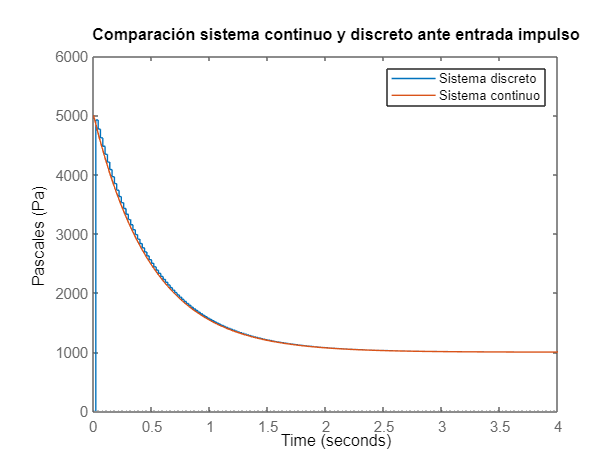

s=tf('s');
Gc=C*inv(s*[1 0;0 1]-A)*B+D;
impulse(Gd,Gc)
title('Comparación sistema continuo y discreto ante entrada impulso')
legend('Sistema discreto','Sistema continuo')
ylabel('Pascales (Pa)');

## 2. Aproximación a sistema de 1º orden

Una vez tenemos calculado el sistema podemos incluir el modelo de la valvula que previamente se nos ha facilitado:


$$K_v=0.4518
$$


Kv=0.4518;

Como hemos podido ver antes, el sistema discretizado cuenta con un par de polos y un cero, uno de esos polos ubicado en 1, lo que el dominio discreto se trata de un integrador. El objetivo es desplazar el integrador del sistema incluyendo una ganancia proporcional hasta el punto de anular el cero del sistema y que así, se comporte como un sistema de primer orden. 

Para seguir la metodología aplicada en el caso continuo, vamos a ubicar el polo en bucle cerrado con un error del 0,1% de la localización del cero. 

Por el momento nos olvidaremos de los sensores.

error=0.1/100;
z2=z1*(1-error)  %Ubicación deseada del polo

z2 = 0.9910

*Recordar que anteriormente ya calculamos el cero del sistema con ayuda del comando zero y lo guardamos en la variable z1*

num=Gd.num{1}; den=Gd.den{1};
Kc=1/(Kv*abs(polyval(num,z2)/polyval(den,z2)))

Kc = 0.0061

Una vez tenemos calculado el control proporcional podemos incluirlo en el bucle externo de realimentación. Podemos verificar el resultado con otras herramientas como rltool.

Gbc=feedback(Gd*Kc*Kv,1)

Gbc =
 
     0.2732 z - 0.271
  ----------------------
  z^2 - 1.688 z + 0.6897
 
Sample time: 0.02 seconds
Discrete-time transfer function.



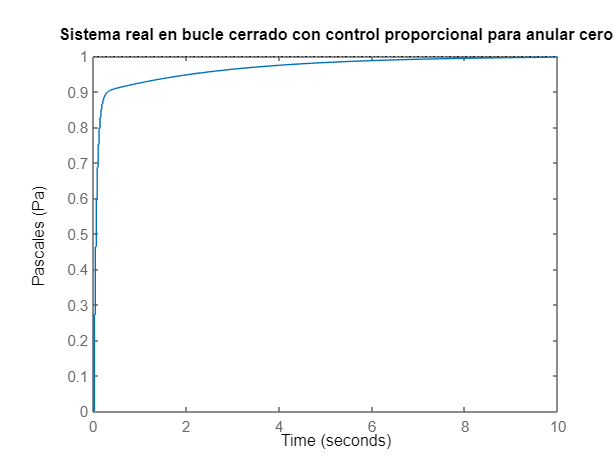

step(Gbc)
title('Sistema real en bucle cerrado con control proporcional para anular cero');
ylabel('Pascales (Pa)');

Como podemos ver, el sistema tiene un comportamiento muy lento, mas adelante sería interesante emplear algunos métodos de control para ver con cual de ellos conseguimos mejor respuesta.

Para ver donde se encuentra exactamente el polo que no hemos anulado anteriormente vamos a hacer uso de rlocus, donde introduciremos el control que acabamos de calcular y elegiremos el polo que ha quedado sin anular.

z3=rlocus(Gd*Kv,Kc)

z3 =     0.9929
    0.6947


G1=tf([0 z3(2)],[1 -z3(2)],T)

G1 =
 
    0.6947
  ----------
  z - 0.6947
 
Sample time: 0.02 seconds
Discrete-time transfer function.



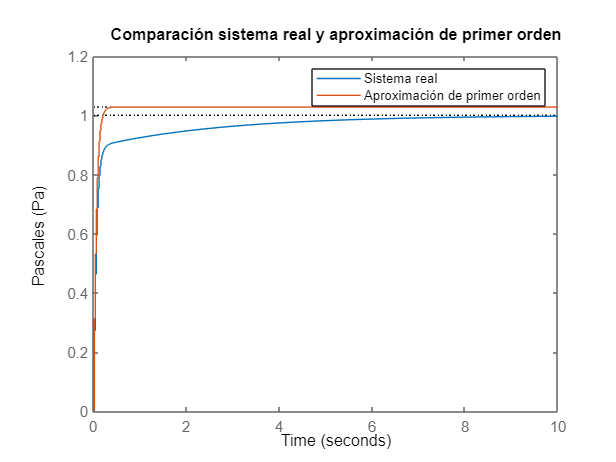

step(Gbc,G1*Kv)
title('Comparación sistema real y aproximación de primer orden');
legend('Sistema real','Aproximación de primer orden');
ylabel('Pascales (Pa)');

Los sistemas se asemejan, pero la aproximación de primer orden tiene un error en régimen permanente,  ya que no cuenta con un integrador.

Ahora, podemos comprobar también el comportamiento del sistema discreto con el continuo, aplicandole el mismo control proporcional.

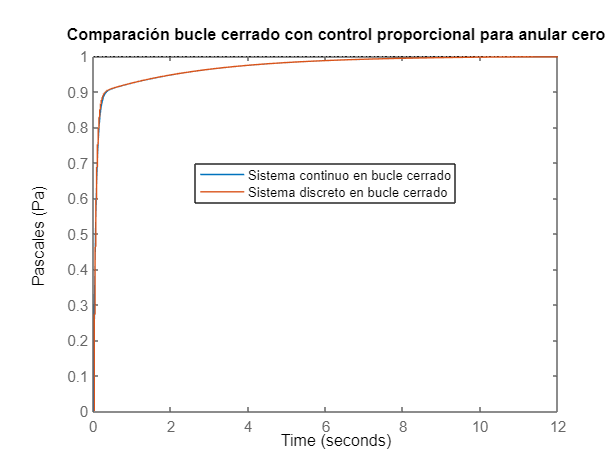

Gcbc=feedback(Gc*Kv*Kc,1);
step(Gcbc,Gbc)
title('Comparación bucle cerrado con control proporcional para anular cero');
legend('Sistema continuo en bucle cerrado','Sistema discreto en bucle cerrado','Location','best');
ylabel('Pascales (Pa)')

## 3. Control del sistema discreto

Para el control del sistema vamos a hacer varias pruebas, ya sea con el sistema real o con la aproximación de primer que debería tener un comportamiento identico. Al finalizar estos experimentos, evaluaremos con cual de ellos obtenemos un mejor resultado y cual de ellos es mas sencillo de implantar en el modelo real.

### 3.1. Control Ackerman con la aproximación de primer orden

En primer lugar, vamos a empezar con el que supongo que puede ser el mas sencillo, que es realizar un control por realimentación de estados por el método de Ackerman. Usaremos la aproximación de primer orden.

Vamos a seguir los siguientes pasos:

- Usando la función **ss() **pasaremos el sistema a descripción interna para así contar con sus matrices de estado.

- Determinaremos los polos deseados para cumplir con un tiempo de establecimiento de 1 segundo.

- Aplicaremos la fórmula de Ackerman para hallar las ganancias necesarias que realimentan el bucle de control.

- Incluiremos un bucle con el tiempo de simulación necesario, añadiendo el control por Ackerman previamente calculado.

- Graficaremos la salida del sistema para ver si su comportamiento se corresponde con los requerimientos deseados.

G1ss=ss(G1);
polos=exp((-4.6/1)*T);
K1=acker(G1ss.A,G1ss.B,polos)

K1 = -0.2174

tsim=2;             %Tiempo de simulación de 2 segundos
N=floor(tsim/T);    %Numero de vueltas que tiene que dar el bucle
x=0;                %Condición inicial nula
K0=1;               
%r=[1*ones(1,floor(N/2)) 0.1*ones(1,ceil(N/2)) ];

*Cambio de referencia inspiración-exhalación, de momento no lo usaremos*

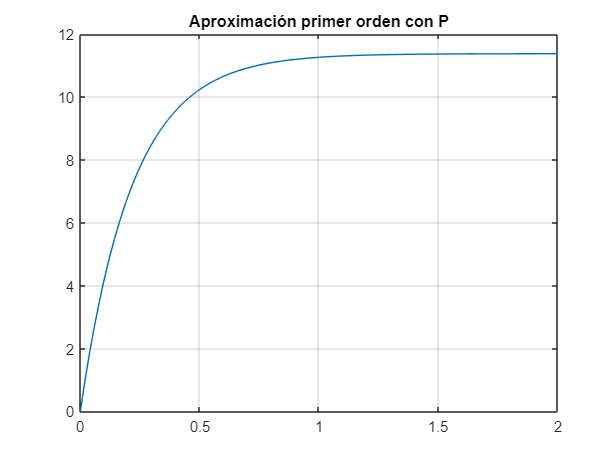

r=1;
for k=1:N
    u(k)=-K1*x(k)+r*K0*G1ss.B;
    x(k+1)=G1ss.A*x(k)+G1ss.B*u(k);
    y1=G1ss.C*x;
end
t=0:T:tsim;
plot(t,x)
grid;
title('Aproximación primer orden con P')

A primera vista parece que tiene un buen comportamiento, pero no se establece en la unidad. Para ello usaremos usaremos una segunda ganancia, calculada a partir de la ganancia estática del sistema. Ésta la usaremos para anular asi su error en regimen permanante.

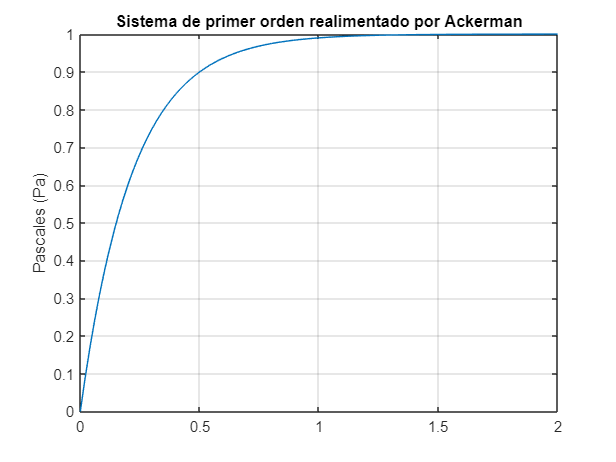

K2=1/y1(end);
y1=y1*K2;
plot(t,y1)
title('Sistema de primer orden realimentado por Ackerman')
ylabel('Pascales (Pa)')
grid;

Para su comprobación usaremos el criterio del 2%

clear I;

*Eliminamos la variable I ya que, en el primer apartado la usamos para nombrar la matriz identidad para la discretización del sistema*

I=find(y1<y1(end)*0.98);            
ts=t(I(end))

ts = 0.8400

Como vemos, el tiempo de establecimiento cumple con la especificación de 1 segundo de tiempo de establecimiento, incluso consiguiendo una respuesta mas rápida de la esperada.

### 3.2. Control de Ackerman con sistema real

La realimentación de estados por el método de Ackerman no ofrece buenos resultados cuando el sistema cuenta con un cero, ya que, esta formula no cuenta con ello. Como sabemos, el lugar de las raices cambía con la existencia de polos, pero también con la ceros y es por ello que no podemos aplicar la formula de Ackerman tal cual. 

El método propuesto es en lugar de asignar un polo dominte y otro alejado para cumplir con las especificaciones, asignar un polo dominante para el cumplimiento de los requerimientos y otro polo en el lugar geométrico donde se anulara el cero del sistema. Así, debería tener un comportamiento similar al calculado en el apartado anterior.

La metodología a seguir es la mencionada anteriormente con el control del sistema de primer orden, con la diferencia que en este caso al tratarse de un sistema de segundo orden, el vector de ganancias de Ackerman será de 2 columnas y es ahí donde nosotros indicaremos la ubicación del polo para anular el cero.

Recordemos que el cero del sistema se encuenta en 0.996.

polos_deseados=exp((-4.6/1)*T);
K11=acker(G,H,[polos_deseados 0.996])

K11 =     0.0006   -0.1092


A partir de aquí, podemos copiar lo programado en el apartado anterior y simplemente cambiar las matrices de espacio de estado a las del sistema real y la condición inicial que en este caso consta de dos estados.

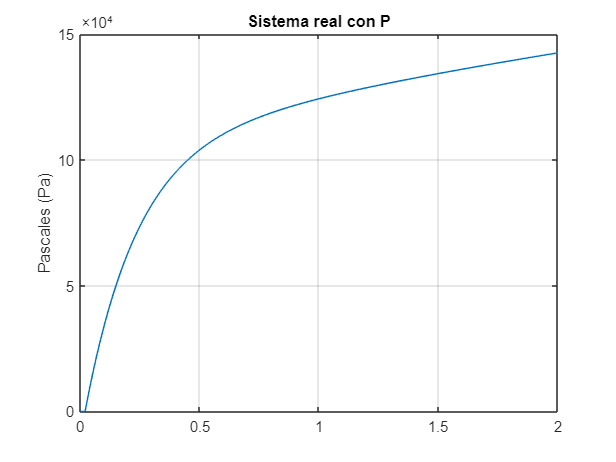

tsim=2;             %Tiempo de simulación de 2 segundos
N=floor(tsim/T);    %Numero de vueltas que tiene que dar el bucle
x=[0;0];            %Condiciones iniciales nulas
K0=1;               
r=[1 1];
clear u;
for k=1:N
    u(k)=-K11*x(:,k)+r*H;
    x(:,k+1)=G*x(:,k)+H*u(k);
    y(k+1)=Cd*x(:,k);
end
t=0:T:tsim;
plot(t,y)
grid;
title('Sistema real con P')
ylabel('Pascales (Pa)')

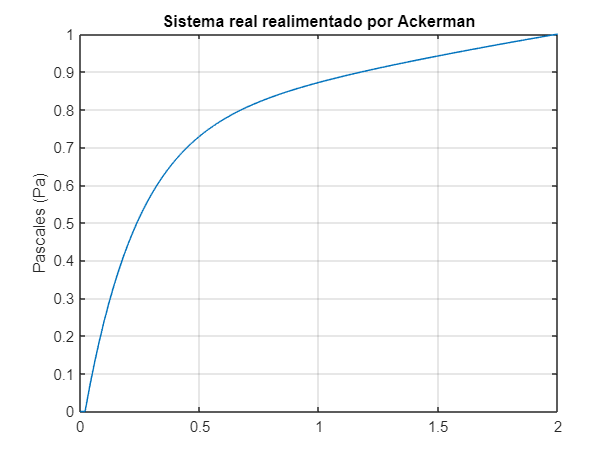

K22=1/y(end);
y=y*K22;
plot(t,y)
title('Sistema real realimentado por Ackerman')
ylabel('Pascales (Pa)')
grid;

clear I;
I=find(y<y(end)*0.98);            
ts=t(I(end))

ts = 1.8000

En este caso el tiempo de establecimiento es de 0.85 segundos, una centésima menor al control que hemos realizado con la aproximación de primer orden. Aun así, el comportamiento de ambos es prácticamente el mismo y ambas respuestas son bastante apropiadas.

Por último vamos a comprobar ambos sistemas y ver que, efectivamente se comportan igual.

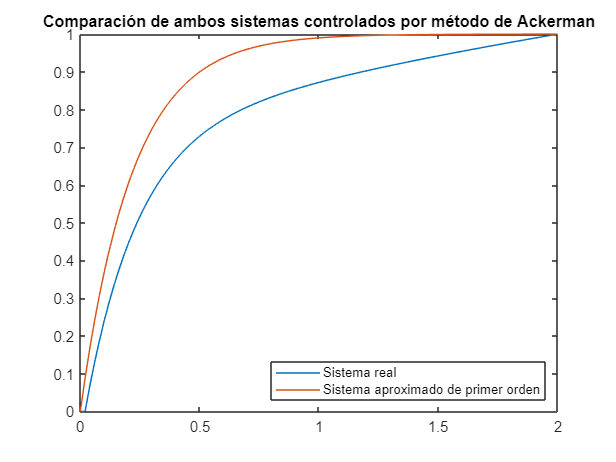

plot(t,y,t,y1);
title('Comparación de ambos sistemas controlados por método de Ackerman')
legend('Sistema real','Sistema aproximado de primer orden','Location','southeast')

### 3.3. Métodos de sintonización de PID

 En este caso, vamos a implantar el método de Ziegler-Nichols para sintonización de PIDs. El sistema real incluida la valvula presenta un comportamiento inestable en bucle abierto, por lo que, en primera instancia, vamos hacer uso de la aproximación de primer orden, que en bucle abierto si tiende a la estabilidad ante una entrada escalón unitario.

#### 3.3.1 Método de Ziegler-Nichols en bucle abierto

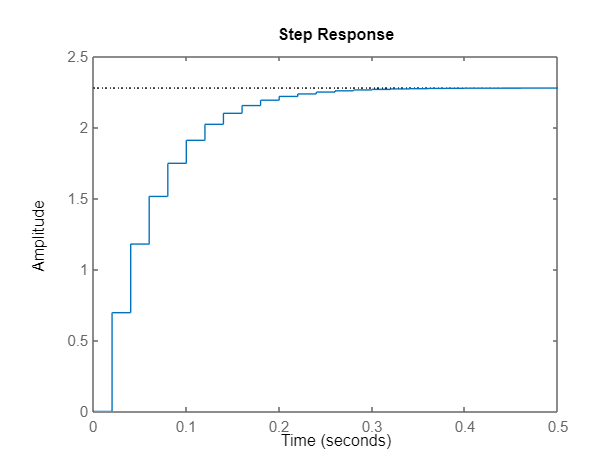

clear Y t;
step(G1)

[Y,t]=step(G1);
i=find(Y<(Y(end)*0.632));
t63=t(i(end)); 
i=find(Y<(Y(end)*0.283)); 
t28=t(i(end));
K=Y(end); 

El parámetro d, al tratarse un controlador digital lo definimos como $d=\frac{T}{2}
$ , donde $T$ es el tiempo de muestreo seleccionado.

d=T/2;
tau=t63-d;
d/tau

ans = 0.3333

El método de Ziegler-Nichols de bucle abierto ofrece buenos resultados para $0.15<\frac{d}{\tau}<0.6$, aún asi vamos a realizar la sintonización y ver su respuesta. Para el calculo de los parámetros $K_p$ y $K_i$ vamos a apoyarnos en la siguiente tabla:

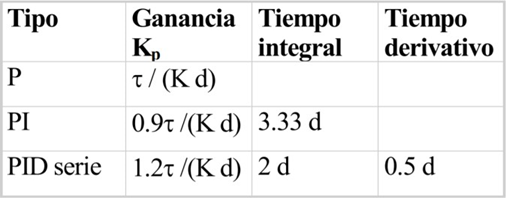

En este caso, sintonizaremos un controlador PI.

Kp=0.9*tau/(K*d);
Ti=3.33*d;
Ki=Kp/Ti;
PI=pid(Kp,Ki,0,0,T)

PI =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 1.19, Ki = 35.6, Ts = 0.02
 
Sample time: 0.02 seconds
Discrete-time PI controller in parallel form.



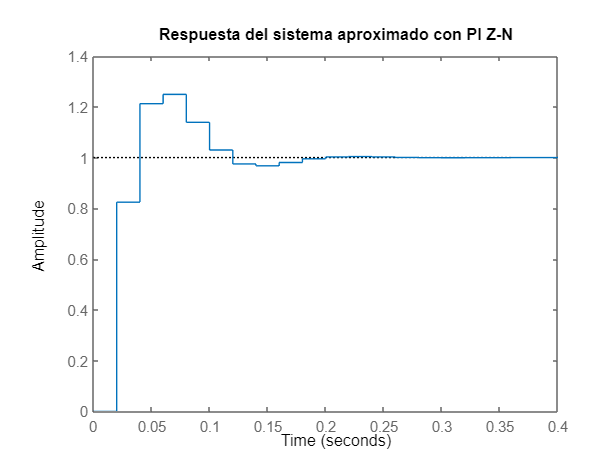

step(feedback(G1*PI,1))
title('Respuesta del sistema aproximado con PI Z-N')

La respuesta con el controlador PI anula su error en régimen permanente, pero su comportamiento consta de una gran sobreoscilación y es demasiado rápido para lo que estamos buscando.

Vamos a ver también su respuesta cuando introducimos un PID serie, apoyandonos nuevamente en la tabla anterior.

Kp=1.2*tau/(K*d);
Ti=2*d;
Td=0.5*d;
Ki=Kp/Ti;
Kd=Kp*Td;
PID=pid(Kp,Ki,Kd,0,T)

PID =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 1.58, Ki = 79.1, Kd = 0.00791, Ts = 0.02
 
Sample time: 0.02 seconds
Discrete-time PID controller in parallel form.



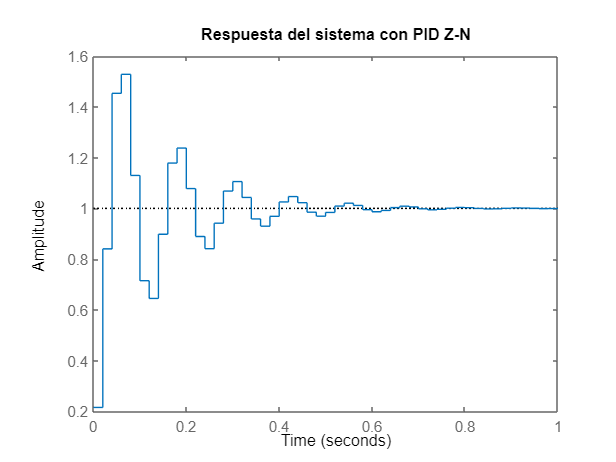

step(feedback(PID*G1,1));
title('Respuesta del sistema con PID Z-N')

La respuesta con la sintonización del PID es incluso pero que la respuesta simplemente con el controlador PI, pareciendo que se encuentra cerca del límite de la estabilidad.

#### 3.3.2 Método de Ziegler-Nichols en bucle cerrado

En el anterior apartado hemos comentado que para poder sintonizar el controlador por el método de Ziegler-Nichols el sistema debía de ser estable en bucle abierto. Optamos por usar la aproximación de 1º orden para poder usarlo, ya que el sistema original no era estable en bucle cerrado. 

El método de Ziegler-Nichols cuenta con una variante para estos casos, la que llamamos el método de Ziegler-Nichols en bucle cerrado. 

Como último método para la sintonización del controlador, vamos a usar directamente el sistema real y vamos a realizar la sintonización del PID con la variante antes comentada.

Este método consiste en llevar el sistema al borde la estabilidad, obteniendo los valores de su ganancia crítica y periodo crítico, a partir de estos datos contamos con una tabla donde simplemente introducimos los datos calculados y obtenemos $K_p
$, $T_i$ y $T_d$, igual que en método de bucle abierto. La tabla en cuestión es la siguiente:

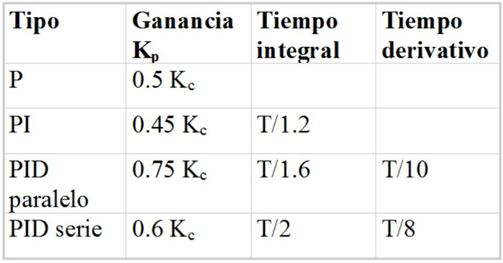

[Mg Mf wcg wcf]=margin(Gd);

Kc=Mg;
Tc=2*pi/wcg;

Vamos a sintonizar un PID paralelo.

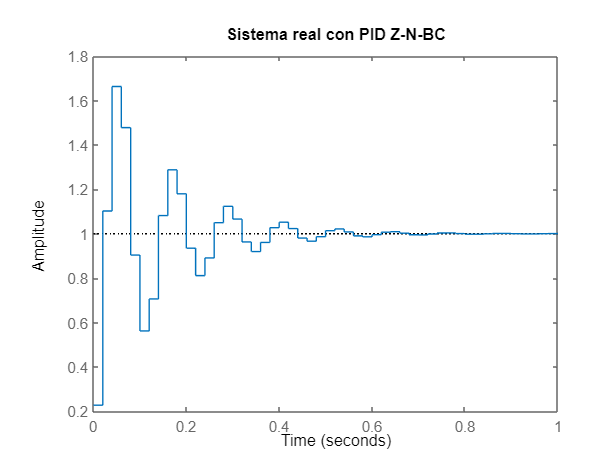

Kp=0.75*Kc;
Ti=Tc/1.6;
Td=Tc/10;
Ki=Kp/Ti;
Kd=Kp*Td;
PID=pid(Kp,Ki,Kd,0,T);
step(feedback(PID*Gd,1));
title('Sistema real con PID Z-N-BC')

La respuesta que obtenemos en este caso tampoco es nada buena.

Aunque por otro lado, hay que ser consciente de que, cumple con lo que nos ofrece el método de Ziegler-Nichols que se fundamenta en que, la respuesta del sistema será buena pero con 1/4 de sobreoscilación en cada una de ellas, llegando a la estabilidad. En nuestro caso, esto no nos sirve ya que al tratarse de un respirador no nos podemos permitir sobreoscilaciones. Tan solo hay que imaginar lo que conllevaría esto para el paciente...

## Conclusiones

En primer lugar, hemos realizado la discretización del sistema analiticamente. En ocasiones anteriores, he realizado la discretización del sistema con ayuda del comando c2d, pero obteniendo malos resultados, siendo el único con buenos resultados la discretización por el método "Tustin". Finalmente, al realizar la discretización analiticamente, hemos podido observar que es la manera mas óptima de realizar una discretización, ya que, los anteriores métodos que he intentado incluir son solo aproximaciones y pueden servir, pero solo como una aproximación.

Seguidamente, he probado con diferentes tiempos de muestreo y podemos ver que tiene un buen comportamiento hasta aproximadamente 0.1 segundos. Al final optamos por un tiempo de muestreo de 0.01 segundos, por el hecho de que ni es un tiempo demasiado pequeño, que sería bastante mas caro computacionalmente, ni un tiempo demasiado alto que podría traer malos resultados y perder demasiada información.

En segundo lugar, tratamos de anular un polo con el cero que contaba en el sistema real, para así, aproximarlo a un sistema de primer orden con el que sería mas fácil trabajar posteriormente. Esto se pudo conseguir incluyendo un bucle interno con un control proporcional. Conseguimos aproximarlo y verificar que su comportamiento era el mismo. Para comprobar también que la aproximación se comportaba de igual forma que el sistema continuo, le aplicamos la misma ganancia proporcional al controlador, y efectivamente, se correspondian.

Una vez conseguido la aproximación de primer orden y comprobado que se comporta de forma similar, lo siguiente sería incluir un control al sistema para que se comporte según las especificaciones requeridas. En este caso, hemos empleados diferentes técnicas para el control, y además probado cual sería mas eficiente y sencillo. 

Teniamos dos opciones:

- Incluir un bucle interno para aproximarlo a un primer orden y a partir de ello, incluir el control del sistema en el bucle de control externo.

- Directamente con el sistema real, incluir el control con unicamente un bucle de control.

Hemos realizado ambas opciones, con el fin de comprobar de que manera se comportaría mejor el sistema y fuese mas sencillo de implementar.

El primero de los experimentos fue con el sistema de primer orden realizar un control por realimentación de estados por Ackerman, lo que nos dío un buen resultado. En segundo lugar, usamos el sistema real y usamos el mismo procedimiento de Ackerman pero en este caso, al tratarse de un sistema de segundo orden, ubicamos uno de los polos del sistema estrategicamente en el lugar donde se anulara con el cero del sistema, ya que como sabemos, el control por Ackerman no ofrece buenos resultados cuando el sistema cuenta con ceros. El resultado fue también bueno, y bajo mi punto de vista está sería la mejor forma de controlar el sistema, pudiendonos olvidar del bucle de control interno y simplemente incluyendo único bucle de control con que llegariamos a las mismas conclusiones que con este.

Por último, realizamos la sintonización de un controlador por el método de Ziegler-Nichols, ya fuese la variante en bucle cerrado o en bucle abierto. Los resultados no fueron los esperados y en general, la peor de las opciones de control. 

Despues de estos experimentos, llegamos a la conclusión que la mejor forma de controlar el sistema sería realizar un único bucle de control con el sistema real e incluir un control de por realimentación de estados de Ackerman anulando el cero del sistema, como hacemos en el apartado 3.2.